%CIFAR10
rootFolder = 'cifar10Train';
categories = {'airplane','automobile','bird','cat','deer','dog','frog','horse','ship','truck'};

%CIFAR100
% rootFolder = 'cifar100Train';
% categories = {'keyboard', 'tulip', 'oak_tree', 'turtle', 'mountain', 'pickup_truck', 'clock', 'otter', 'whale', 'lawn_mower', 'girl', 'sunflower', 'elephant', 'tiger', 'plate', 'crocodile', 'butterfly', 'hamster', 'tank', 'orchid', 'snake', 'squirrel', 'lion', 'camel', 'bottle', 'lizard', 'bee', 'maple_tree', 'shark', 'mushroom', 'television', 'rabbit', 'sea', 'house', 'streetcar', 'couch', 'skyscraper', 'shrew', 'beetle', 'pine_tree', 'aquarium_fish', 'leopard', 'lobster', 'telephone', 'raccoon', 'road', 'cattle', 'cloud', 'kangaroo', 'crab', 'castle', 'lamp', 'man', 'bed', 'forest', 'poppy', 'dolphin', 'rocket', 'orange', 'mouse', 'flatfish', 'sweet_pepper', 'baby', 'pear', 'skunk', 'wardrobe', 'porcupine', 'bridge', 'chair', 'can', 'cockroach', 'wolf', 'willow_tree', 'motorcycle', 'snail', 'plain', 'tractor', 'seal', 'trout', 'palm_tree', 'possum', 'worm', 'cup', 'dinosaur', 'fox', 'ray', 'rose', 'bicycle', 'bus', 'table', 'caterpillar', 'boy', 'chimpanzee', 'train', 'bowl', 'woman', 'beaver', 'spider', 'apple', 'bear'};

%COREL80
% rootFolder = 'CorelDB';
% categories = {'art_dino', 'bld_sculpt', 'obj_aviation', 'obj_car', 'obj_door', 'obj_moleculr', 'pet_cat', 'sc_', 'sc_iceburg', 'sc_rural', 'texture_1', 'texture_6', 'wl_eagle', 'wl_horse', 'wl_owls', 'wl_wolf', 'art_mural', 'eat_drinks', 'obj_balloon', 'obj_cards', 'obj_eastregg', 'obj_orbits', 'pet_dog', 'sc_autumn', 'sc_indoor', 'sc_sunset', 'texture_2', 'wl_buttrfly', 'wl_elephant', 'wl_lepoad', 'wl_porp', 'woman', 'art_1', 'bld_castle', 'eat_feasts', 'obj_bob', 'obj_decoys', 'obj_flags', 'obj_ship', 'pl_flower', 'sc_cloud', 'sc_mountain', 'sc_waterfal', 'texture_3', 'wl_cat', 'wl_fish', 'wl_lion', 'wl_primates', 'art_antiques', 'bld_lighthse', 'fitness', 'obj_bonsai', 'obj_dish', 'obj_mask', 'obj_steameng', 'pl_foliage', 'sc_firewrk', 'sc_night', 'sc_waves', 'texture_4', 'wl_cougr', 'wl_fox', 'wl_lizard', 'wl_roho', 'art_cybr', 'bld_modern', 'obj_234000', 'obj_bus', 'obj_doll', 'obj_mineral', 'obj_train', 'pl_mashroom', 'sc_forests', 'sc_rockform', 'sp_ski', 'texture_5', 'wl_deer', 'wl_goat', 'wl_nests', 'wl_tiger'};

imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imagesPerClass = 100;
[trainingSet, testingSet] = splitEachLabel(imds, imagesPerClass, 'randomize'); 

% featureSet = [];
ref = [];
numImages = numel(trainingSet.Files);
featureSet = zeros(numImages, 64 + 1764, "double"); % glcm + hog features

% preprocess the images in the dataset and collect:
% - their SIFT features into the featureSet matrix
% - their original image ID into the ref vector
for i = 1 : numImages
    I = im2gray(readimage(trainingSet,i));
    
    % corners
    % no_corners = getnoofconers (I);

    % GLCM
    glcm = graycomatrix(I, 'NumLevels', 8, 'GrayLimits', []);
    
    % HOG
    [hog_4x4, vis4x4] = extractHOGFeatures(I, 'CellSize', [4 4]);

    featureSet(i, :) = cat(2, reshape(glcm,[1,64]), hog_4x4); 
%     featureSet(i, :) = reshape(glcm,[1,64]); 

end

featureSet = featureSet.'

featureSet =      4     4     9    17    25    11    19     7    20    32    10    21   536     4    44    17    50    77     5   109     4   130     8    37   431     2    12    19    19     0   108    12     3     0    68     8    11     6     1    44    70     7    37    16    42    46   215     3     1     0
     2     8     7     6     9     7     9     5     6    13     5     8    30     1    23    15    22    18     1    33     2    27     8     9    53     1     7     4     1     2     9     3     3     1    12     8     9     6     0    19    12     2    14     6     4    11    57     1     1     0
     2     4     0     6     2     3     4     1     1     1     2     0     5     1     4     1     2     3     2     3     0     3     2     2     2     1     1     3     2     1     3     2     0     0     2     6     1     2     1     1     2     2     2     3     1     3     4     0     2     2
     0     2     0     1     1     0     2     0     1     0     0     0     0     1

% construct LSH hash tables for featureSet
cd('C:\Users\PC\Desktop\3081\Content-based-Image-Retrieval\vLSH')

% Tune hyperparameters
% Q = 144;  % # of queries
K = 32;   % # of nearest neighbors to search for each query
L = 10;   % # of tables
M = 10;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(featureSet, L, M, W);

Creating table 1/10
	Projecting data...
	100 buckets
	min / max size: 1 / 156
	mean / median: 10 / 2
Creating table 2/10
	Projecting data...
	98 buckets
	min / max size: 1 / 217
	mean / median: 1.020408e+01 / 2
Creating table 3/10
	Projecting data...
	92 buckets
	min / max size: 1 / 355
	mean / median: 1.086957e+01 / 2
Creating table 4/10
	Projecting data...
	74 buckets
	min / max size: 1 / 166
	mean / median: 1.351351e+01 / 3
Creating table 5/10
	Projecting data...
	133 buckets
	min / max size: 1 / 105
	mean / median: 7.518797e+00 / 2
Creating table 6/10
	Projecting data...
	104 buckets
	min / max size: 1 / 251
	mean / median: 9.615385e+00 / 2
Creating table 7/10
	Projecting data...
	117 buckets
	min / max size: 1 / 114
	mean / median: 8.547009e+00 / 2
Creating table 8/10
	Projecting data...
	74 buckets
	min / max size: 1 / 452
	mean / median: 1.351351e+01 / 2
Creating table 9/10
	Projecting data...
	101 buckets
	min / max size: 1 / 233
	mean / median: 9.900990e+00 / 2
Creating table 

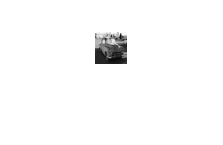

% query an input image
I = imread("car2.jpg");
I = imresize(im2gray(I), [32 32]);
figure, imshow(I); 


% GLCM
glcm = graycomatrix(I, 'NumLevels', 8, 'GrayLimits', []);

% HOG
[hog_4x4, vis4x4] = extractHOGFeatures(I, 'CellSize', [4 4]);

queryFeatures = cat(2, reshape(glcm,[1,64]), hog_4x4); 
% queryFeatures = reshape(glcm,[1,64]); 
queryFeatures = queryFeatures.';

% [idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(featureSet(:, 1:Q), featureSet, lshStruct, K, T);
[query_ids, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(queryFeatures, featureSet, lshStruct, K, T);

Retrieving candidates from table 1
	-----> 0.039018 seconds
Retrieving candidates from table 2
	-----> 0.018839 seconds
Retrieving candidates from table 3
	-----> 0.016841 seconds
Retrieving candidates from table 4
	-----> 0.016893 seconds
Retrieving candidates from table 5
	-----> 0.015919 seconds
Retrieving candidates from table 6
	-----> 0.024939 seconds
Retrieving candidates from table 7
	-----> 0.017922 seconds
Retrieving candidates from table 8
	-----> 0.018411 seconds
Retrieving candidates from table 9
	-----> 0.010228 seconds
Retrieving candidates from table 10
	-----> 0.015159 seconds
Removing duplicate candidates...
	-----> 0.001838 seconds
Performing knn search...
	-----> 0.000584 seconds
Calculating candidate sizes...
	-----> 0.000561 seconds


% aggregate and weight the image features by their ranks 
uniqImageIds = unique(query_ids);
N = numel(uniqImageIds);
weights = zeros(N,1);
fib = zeros(1, K); fib(K-1) = 1;
for i = K-2:-1:1
   fib(i) = fib(i+1)+fib(i+2);
end

for k = 1 : N
    weights(k) = sum(sum(query_ids == uniqImageIds(k))); % unranked weighting of NNs
    % ranked weighting of NNs
    % weights(k) = sum((K + (0 : K - 1) * -1) * (oriImages == uniqImageIds(k)));  % linear
    % weights(k) = sum(flip(exp(1 : K)) * (oriImages == uniqImageIds(k))); % exponential
    % weights(k) = sum(fib * (oriImages == uniqImageIds(k))); % fibonacci
end

ranks = sortrows([weights uniqImageIds], 1, 'descend');


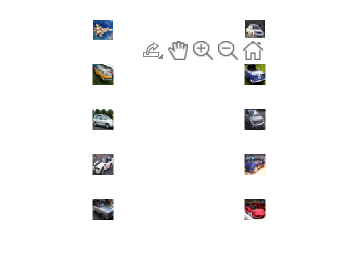

% display top 20 the matching images
figure;
offset = 0;
for pic = 1 : min(11, length(ranks))
    if pic - offset > 10
        break;
    end
    if ranks(pic,2) == 0
        offset = 1;
    end
    if ranks(pic,2)>0
        % plot original image
        I = readimage(trainingSet, ranks(pic, 2));
        subplot(5,2,pic - offset), imshow(I); 
    end
end

cd('..')